The unknown functions (just the base functions, not derivatives) are: Ff(t),N(t),theta(t),vx(t),vy(t)
Initial Conditions:
Y0/YP0:
Ff: 2.289996 Fft:0.000000
N: 8.828080 Nt:0.000000
theta: 0.785398 thetat:0.000000
vx: 0.000000 vxt:2.289996
vy: 0.000000 vyt:-0.981920
Dthetat: 0.000000 Dthetatt:-32.719159


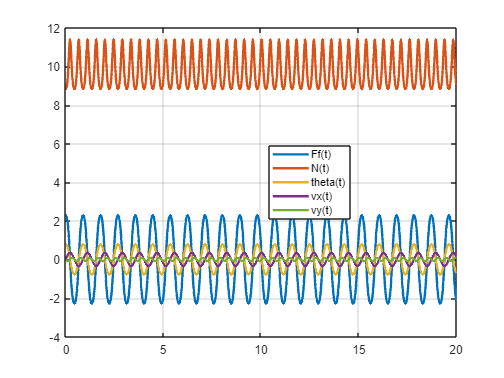


%Set up equations for a rolling semicircle, but phrase it in terms of
%velocity. 
clear all 
syms vx(t) vy(t) theta(t) Ff(t) N(t)

%Set up equations for a rolling semi-circle. Notice that the roll
%conditions are given in terms of a derivative.  This will have an impact
%in a second. 

m = 1;      % kg
r = 0.1;    % m
g = 9.81;     % m/s^2
Izz = m*r^2*(1/4 - 16/9/pi^2) + m*r^2/4;
R_b_I = [cos(theta(t)) -sin(theta(t)) 0;sin(theta(t)) cos(theta(t)) 0;0 0 1];

vG=[vx(t);vy(t)];
F=[Ff(t);N(t)];

% Newton's 2nd
eq1=m*diff(vG,t)==F-m*g*[0;1];

% Euler's 2nd
r_CP_G = [0;-r;0] + R_b_I*[0;4*r/3/pi;0];
MG=cross(r_CP_G,[F;0]);
eq2=Izz*diff(theta(t),t,t)==MG(3);

% roll without slip
vGr = cross([0;0;diff(theta(t),t)],-r_CP_G);
eq3 = vG == vGr(1:2);

DES=[eq1;eq2];
disp_const=[];
vel_const=[eq3];

omega0=0; 
theta0=pi/4;

soln=mechanicsAsDAE(DES,disp_const,vel_const,[0,20],{theta==theta0,diff(theta)==omega0});